# MPC performs poorly in control101

This livescript is a brief manual in support of the app ***mpcfailing_control101.mlapp***.   This is a simple interface to understand and investigate how the core parameters within an MPC law affect the decision making and performance and more specifically, to show that with some systems, tuning can be quite challenging and many choices lead to very poor or even unstable closed-loop performance. We assume that readers have already engaged with the app ***mpctuning_control101.mlapp*** before using this one.

Predictions are core to the advanced control technique of model predictive control (MPC) and thus understanding their role is essential before engaging with MPC. The tuning parameters dictate the performance index used to determine the 'optimal' current control and thus their choice is important. However, it can be seen that different choices lead to hugely variable behaviour and thus understanding what constitute good and bad choices is essential. 

- For more help on how to get the most of this app, please see the videos [here](https://www.youtube.com/playlist?list=PLs7mcKy_nInHEjth9P3m_bxd6D24IVSzz).

- For more information on the supporting files for MPC, please see the following livescripts: ***mpcsourcecode_control101.mlx.***

For more background on MPC readers can look at the website [https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook](https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook) and also a range of popular text books such as that by the author: **A first course in predictive control: 2nd Edition**,  J.A. Rossiter, CRC Press (Taylor and Francis group), 2018, ISBN 9781138099340.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- MPC context

- Challenging scenarios

- Interface and user interaction

## 1. MPC context

Rather than repeating the same information, the reader is invited to read the file ***mpctuning_control101_manual.mlx ***for general background on MPC and tuning***. ***

The underlying code used in this app to form predictions, control laws and closed-loop simulations is the same as discussed in ***mpcsourcecode_control101.mlx.***

The core purpose of the app is to allow the user to explore how the closed-loop behaviour varies hugely with different choices of horizons and weights, as well as with some uncertainty. While it is possible to get good behaviour, the sensitivity to the design choices and the lack of consistency of insight demonstrates core weakenesses in finite horizon MPC which users need to be aware of to use the approach well. It is also an indication of scenarios where finite horizon MPC may be a poor choice.

## 2 Challenging scenarios

The main purpose of this app is to give more exposure to systems with challenging dynamics and explore how this impacts on the ability of MPC to produce effective closed-loop control. We know from the literature that, in principle at least, with large input and output horizons MPC should produce a sensible result. However, those insights are based on perfect number crunching and so some extent rely on optimal control theory which avoids explicit prediction. In practice there are many reasons why the use of large horizons may not be easy or possible, constraint handling being a significant one of these.

The specific models coded into the app as follows:


$$\begin{array}{l}
G=\frac{0\ldotp 2z^{-1} }{1-1\ldotp 2z^{-1} };\;G=\frac{0\ldotp 1z^{-1} +0\ldotp 1z^{-2} }{1-1\ldotp 5z^{-1} +0\ldotp 95z^{-2} };\;\\
G=\frac{0\ldotp 05z^{-1} +0\ldotp 03z^{-2} }{1-2\ldotp 08z^{-1} +1\ldotp 38z^{-2} -0\ldotp 3z^{-3} };\;G=\frac{-0\ldotp 2z^{-1} +0\ldotp 3z^{-2} }{1-1\ldotp 9z^{-1} +1\ldotp 18z^{-2} -0\ldotp 24z^{-3} }
\end{array}$$


These are unstable, under-damped, stiff and non-minimum phase.

Users can recreate the simulations themselves using the code examples in ***mpcsourcecode_control101.mlx.***

### 2.1 Unstable open-loop processes

In practice, explicit prediction is needed, at the very least for constraint handling which will be discussed in later resources. This can cause problems when the local implementation is using limited precision computing. This is a particular problem with open-loop unstable systems as the predictions are divergent which mean the prediction matrices quickly have numbers over a large range and limited precision computing will start to introduce significant errors in the computation of the control law.

We can illustrate this with the following figures. Note the signicant changes in behaviour as the output horizon gets large and indeed some of the curves do not even converge to the correct steady-state! Moreover, even with what seems sensible large horizons, it is possible to get closed-loop instability; this is caused by numerical ill-conditionning rather than a failure of the theory.

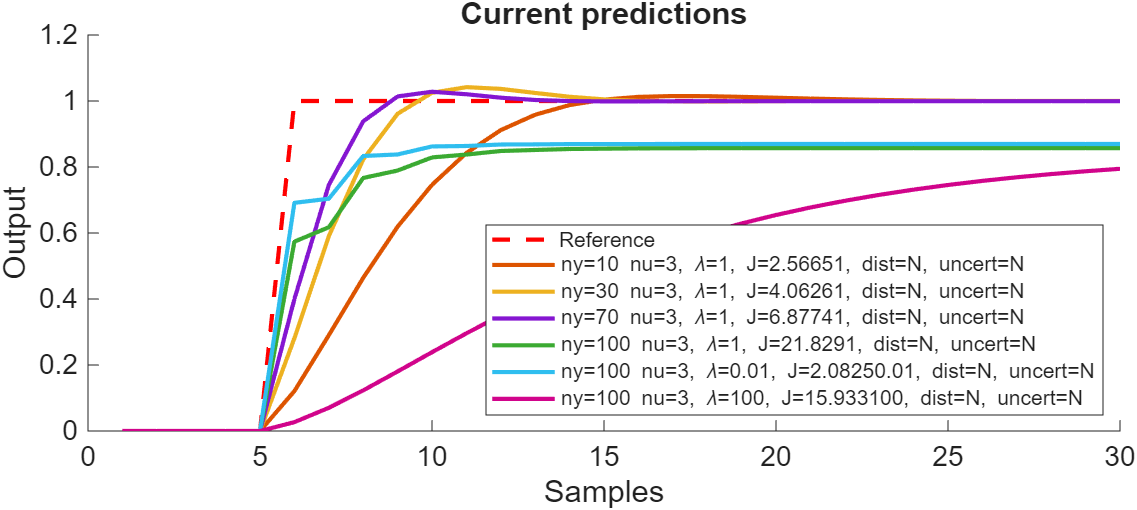

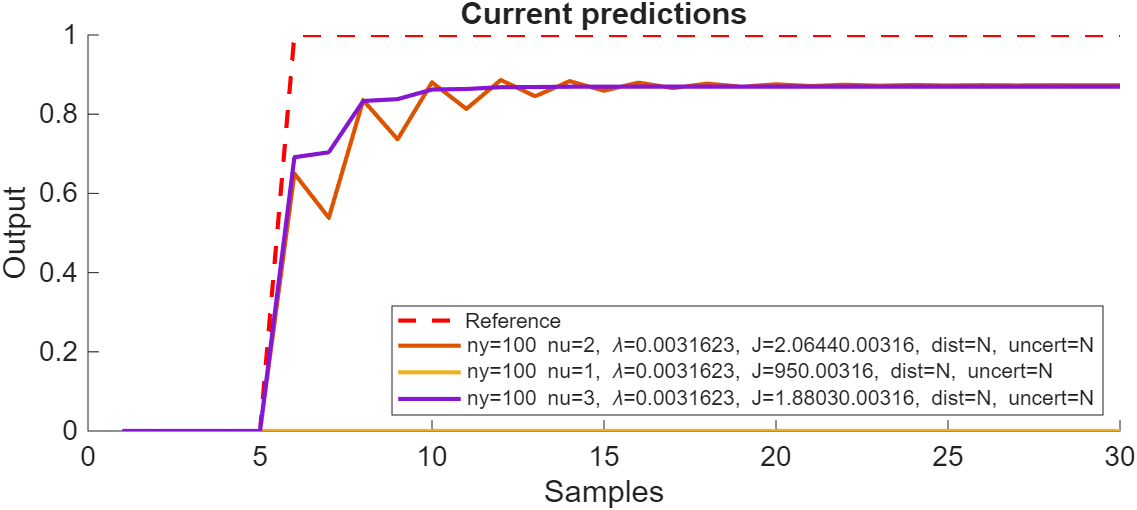

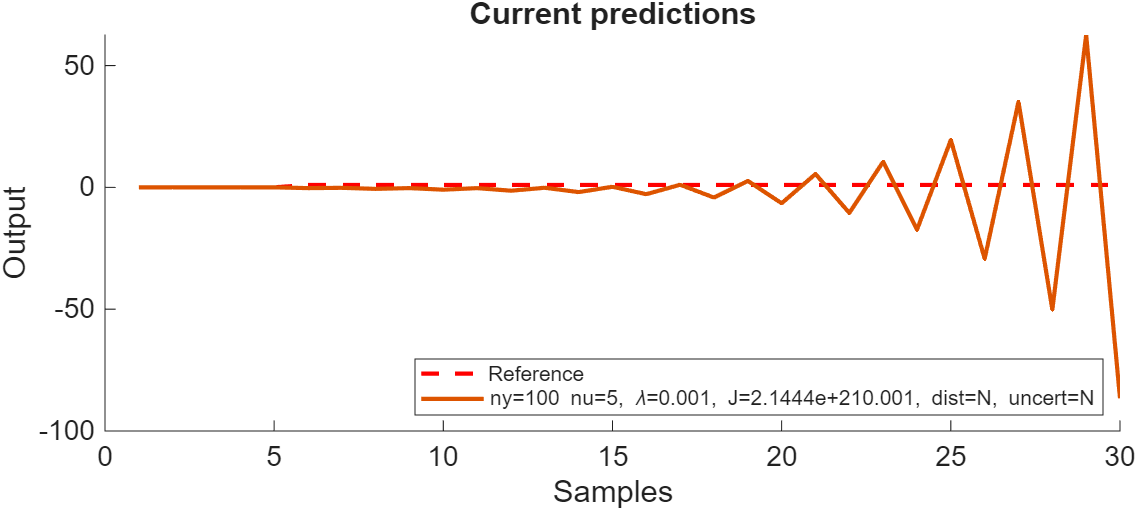

### 2.2. Oscillatory systems

The difficulty with open-loop oscillatory systems is that one can only cancel the oscillation in the behaviour by an appropriately design input, whereas in practice the input horizon and/or output horizon, are often chosen to be too small to be effective for this. Some illustrations below again indicate the wide variety of behaviour that can result, even with what appear sensible choices of tuning parameters. It will also be clear from the input plots that removing the output oscillation requires substantial input activity.

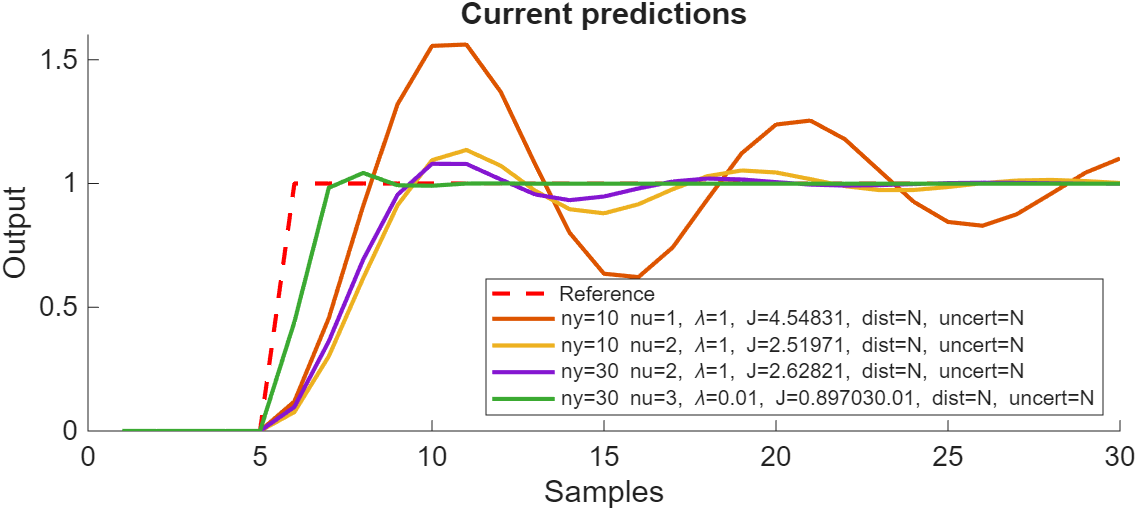

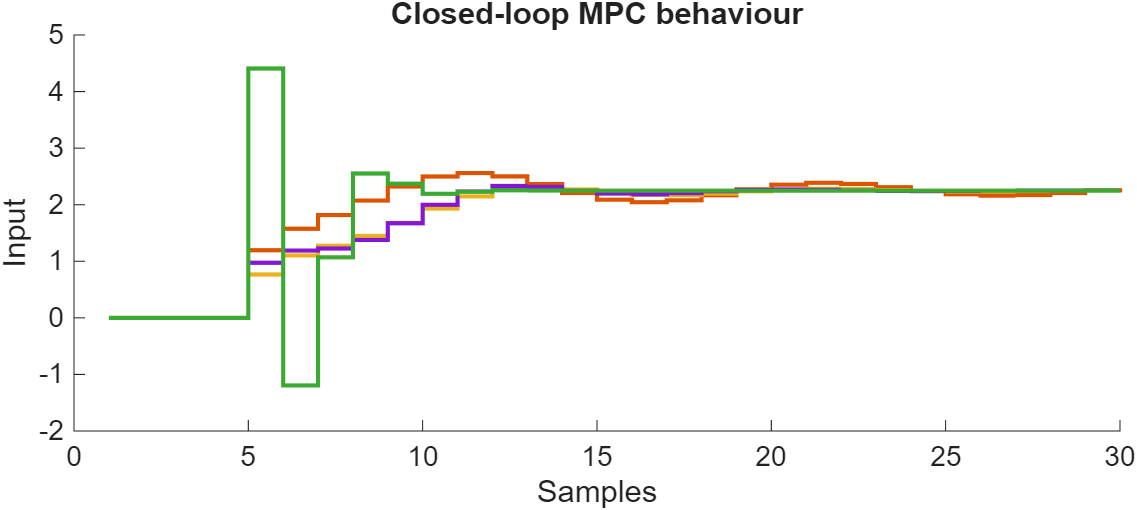

### 2.3 Stiff systems

A stiff system is one with poles covering a wide range of bandwidths. MPC may struggle with these unless the horizons are well chosen as different choices will  emphasise different aspects of the behaviour. It will be clear below that with nu=1, increasing the output horizon is counter-productive because it over-emphasises the steady-state at the expense of very slow transients. Faster trasnients of course do not come for free and required aggressive input action.

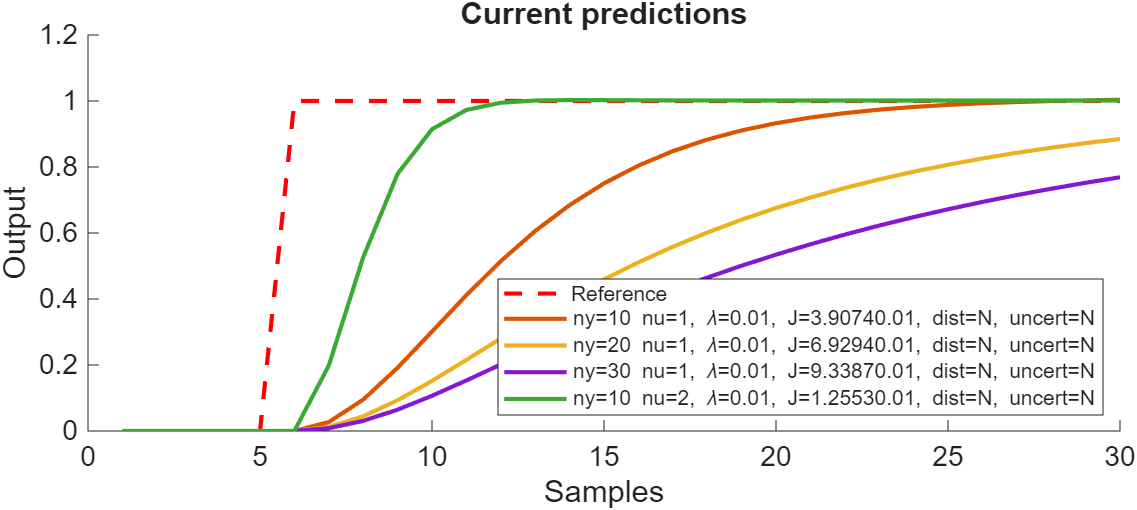

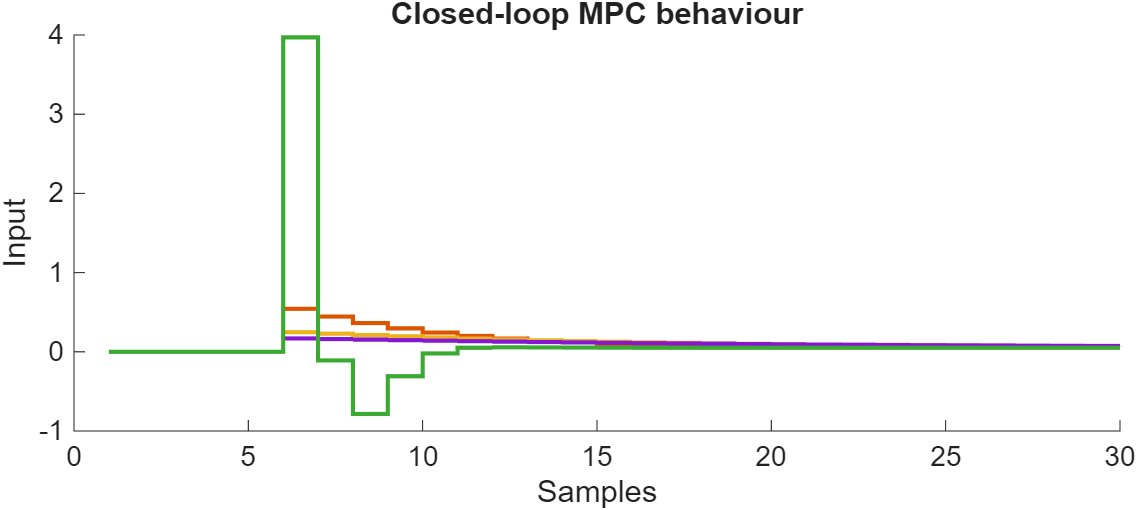

### 2.4 Non-minimum phase systems

This option shows similar challenges as the above ones, that is, a wide variety in closed-loop behaviour as the horizon and weights are changed. One can even get instability quite easily.

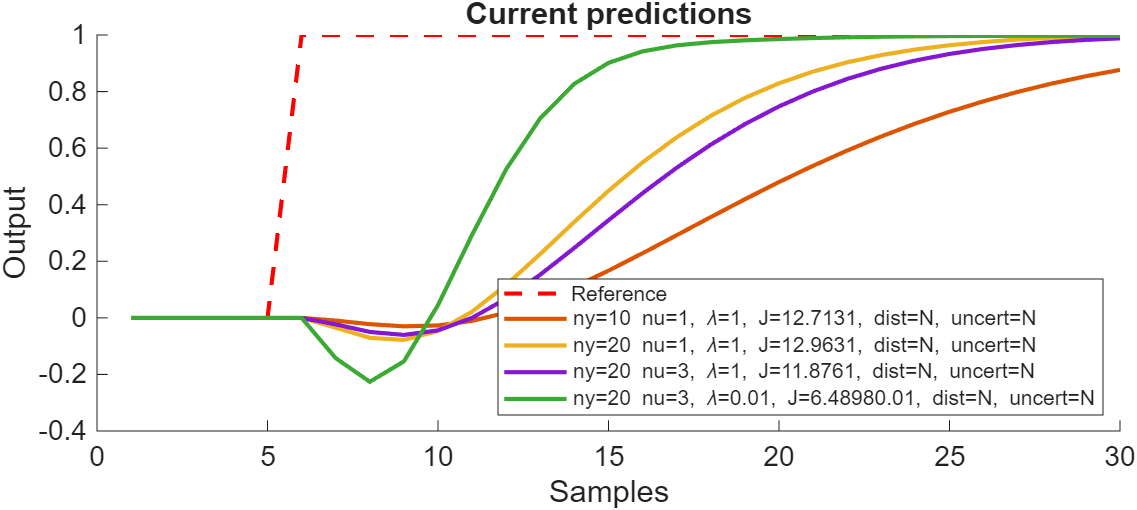

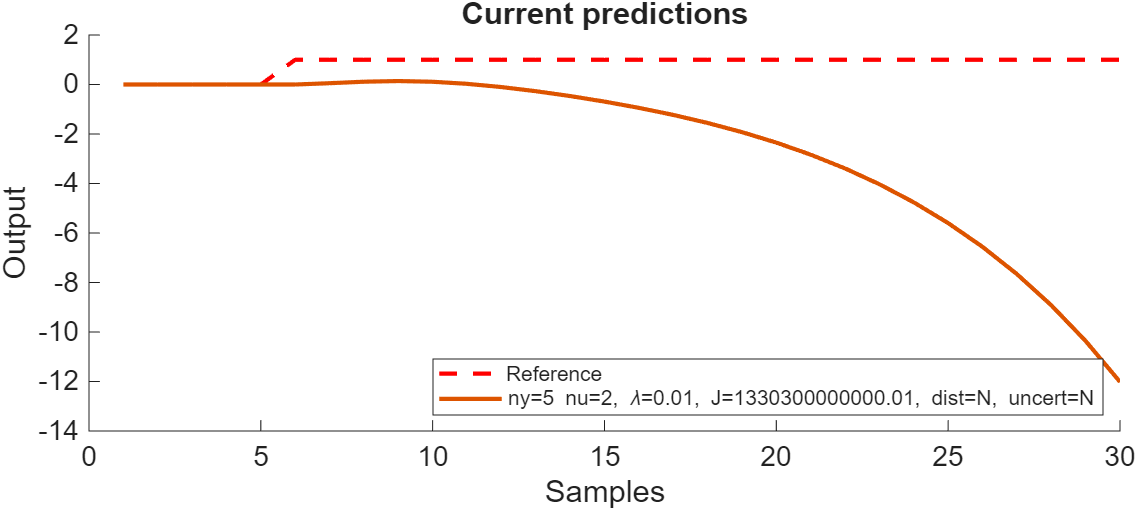

## 4. Interface and user interaction

The main purpose of the app is to allow users to explore the behaviours that arise when using MPC on systems with challenging behaviours and determine, through trial, error and reflection, some good practice guidelines.

The app itself is self-explanatory as shown in the screen capture below. Users can also add some output disturbances and parameter uncertainty to explore the impact of these. For simplicity the underlying systems are fixed.

###